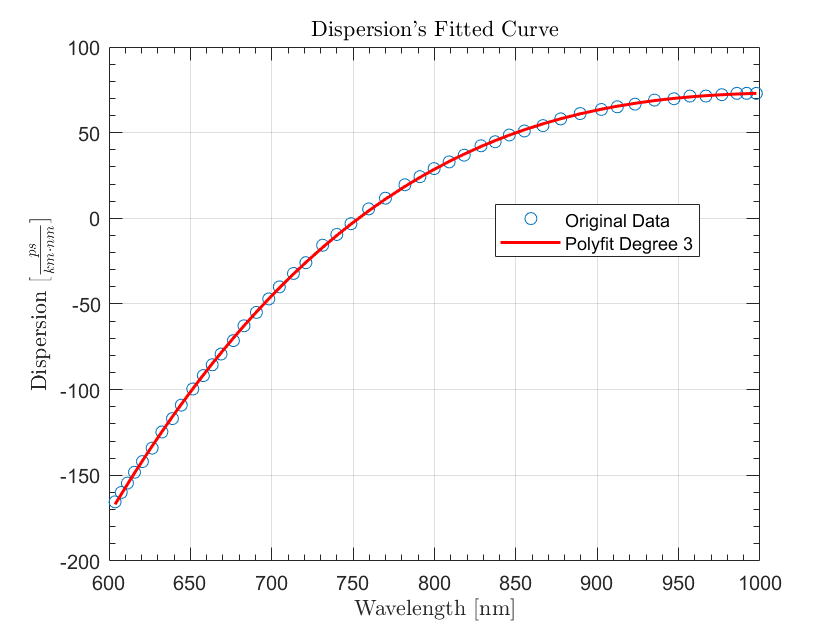

% Load the data from CSV file
data = readmatrix('data.csv'); % Replace 'data.csv' with your file name
data2 = readmatrix('dataRefract.csv');

% Extract columns for wavelength and dispersion
wavelength = data(:, 1);  % First column: Wavelength (nm)
dispersion = data(:, 2);  % Second column: Dispersion (ps/(km*nm))

% Fit a polynomial of degree n (e.g., 3rd-degree polynomial)
n = 3;
coeffs = polyfit(wavelength, dispersion, n);

% Generate the fitted curve
fitted_dispersion = polyval(coeffs, wavelength);

% Plot the original data and the fitted curve
plot(wavelength, dispersion, 'o', 'DisplayName', 'Original Data');
hold on;
plot(wavelength, fitted_dispersion, '-', 'DisplayName', ['Polyfit Degree ' num2str(n)], "LineWidth", 1.5, "Color", [1 0 0]);
xlabel('Wavelength [nm]', "Interpreter", "latex");
ylabel('Dispersion $[\frac{ps}{km \cdot nm}]$', "Interpreter", "latex");
legend("Location","best");
title('Dispersion''s Fitted Curve', "Interpreter", "latex");
hold off;
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);

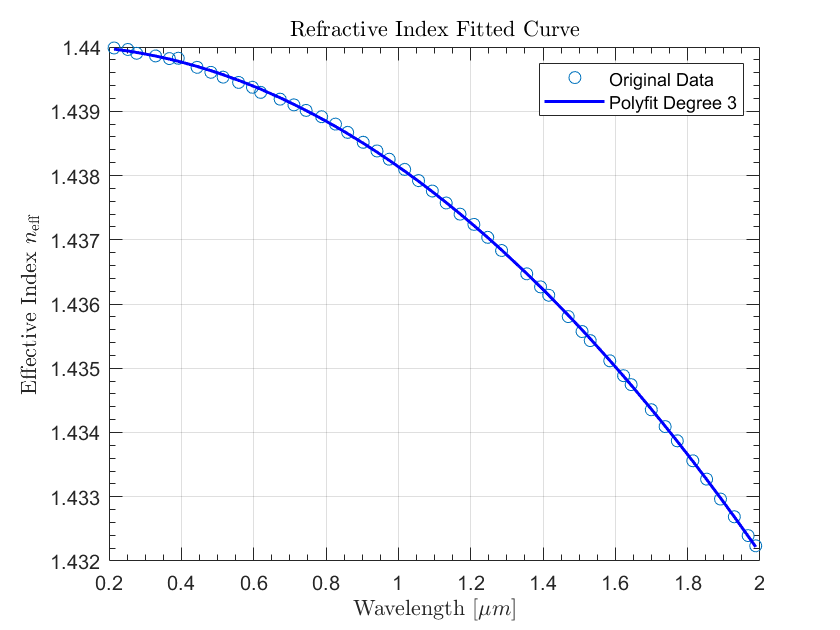



% Extract columns for wavelength and refractive index
wavelength_microns = data2(:, 1);  % First column: Wavelength (microns)
n_eff = data2(:, 2);               % Second column: Effective refractive index

% Fit a polynomial of degree n (e.g., 3rd-degree polynomial)
n_poly = 3;
coeffs_refract = polyfit(wavelength_microns, n_eff, n_poly);

% Generate the fitted curve
fitted_refract = polyval(coeffs_refract, wavelength_microns);

% Plot the original refractive index data and the fitted curve
figure;
plot(wavelength_microns, n_eff, 'o', 'DisplayName', 'Original Data');
hold on;
plot(wavelength_microns, fitted_refract, '-', 'DisplayName', ['Polyfit Degree ' num2str(n_poly)], "LineWidth", 1.5, "Color", [0 0 1]);
xlabel('Wavelength [$\mu m$]', "Interpreter", "latex");
ylabel('Effective Index $n_{\mathrm{eff}}$', "Interpreter", "latex");
legend("Location", 'northeast');
title('Refractive Index Fitted Curve', "Interpreter", "latex");
hold off;
grid on;
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);